Mikołaj Suchon Report

%define variables
syms a b
%define data
x=[1,2,3,4];
y=[7,6,4,1];
%define your function
f=0;
for i=1:length(x)
f=f+((a*x(i)+b)-y(i))^2;
end
%calculate derivatives
da=diff(f,a);
db=diff(f,b);
%solve the equations
sol=solve([da==0,db==0],[a,b]);
disp(sol);

    a: -2
    b: 19/2



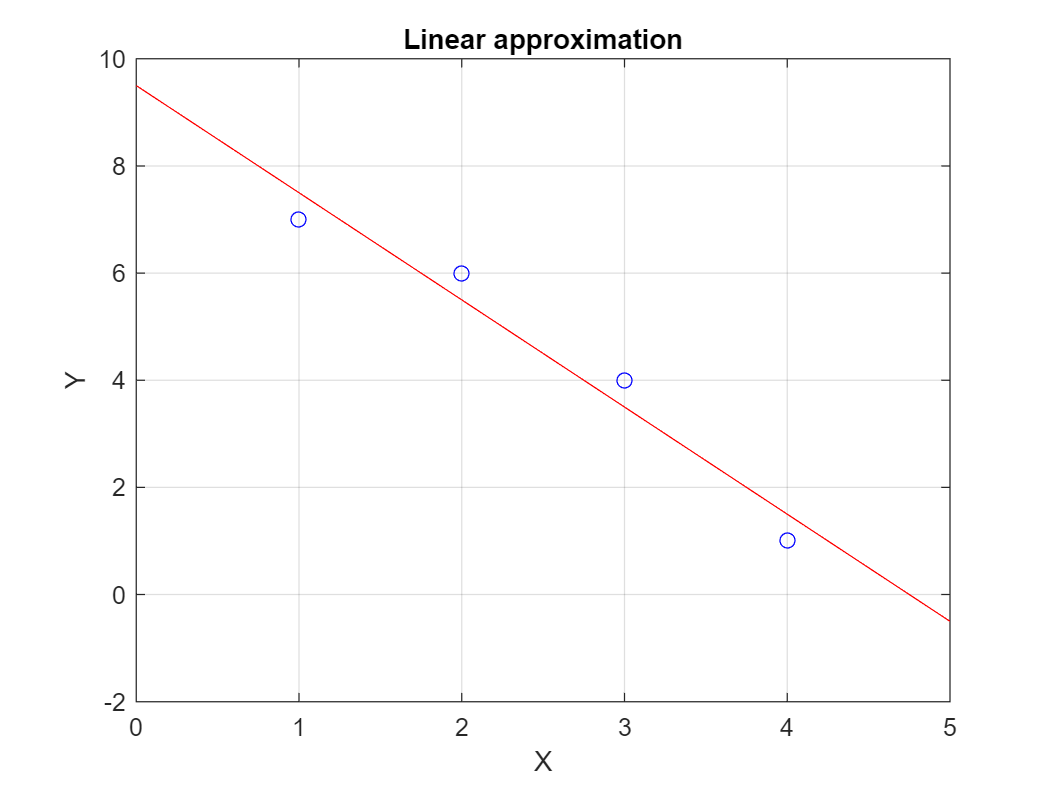

%plot the solution
x1=0:0.1:5;
y1=sol.a*x1+sol.b;
figure(1)
plot(x1,y1,'r');
hold on;
plot(x,y,'bo');
hold off; grid on;
xlabel('X'), ylabel('Y'),
title('Linear approximation')

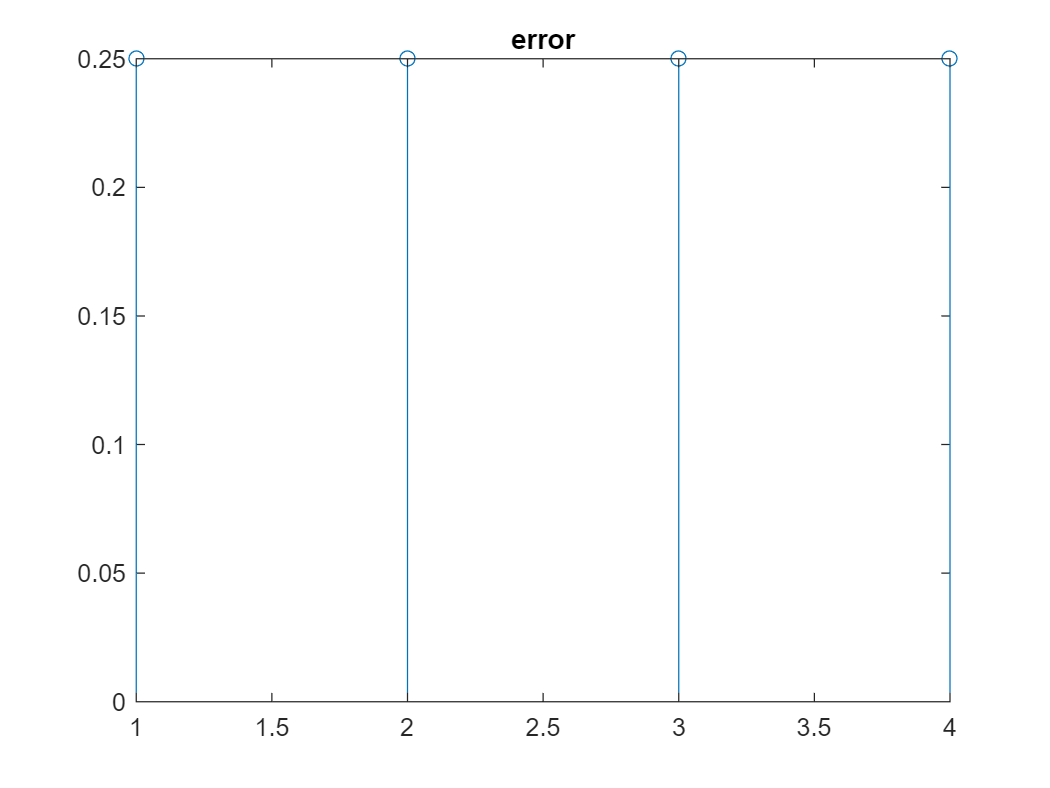


%error
x1=1:4;
y1=sol.a*x1+sol.b;
e=(y1-y).^2;
stem(e)
title('error')

%polyfit
[a]=polyfit(x,y,2);
disp(a);

   -0.5000    0.5000    7.0000



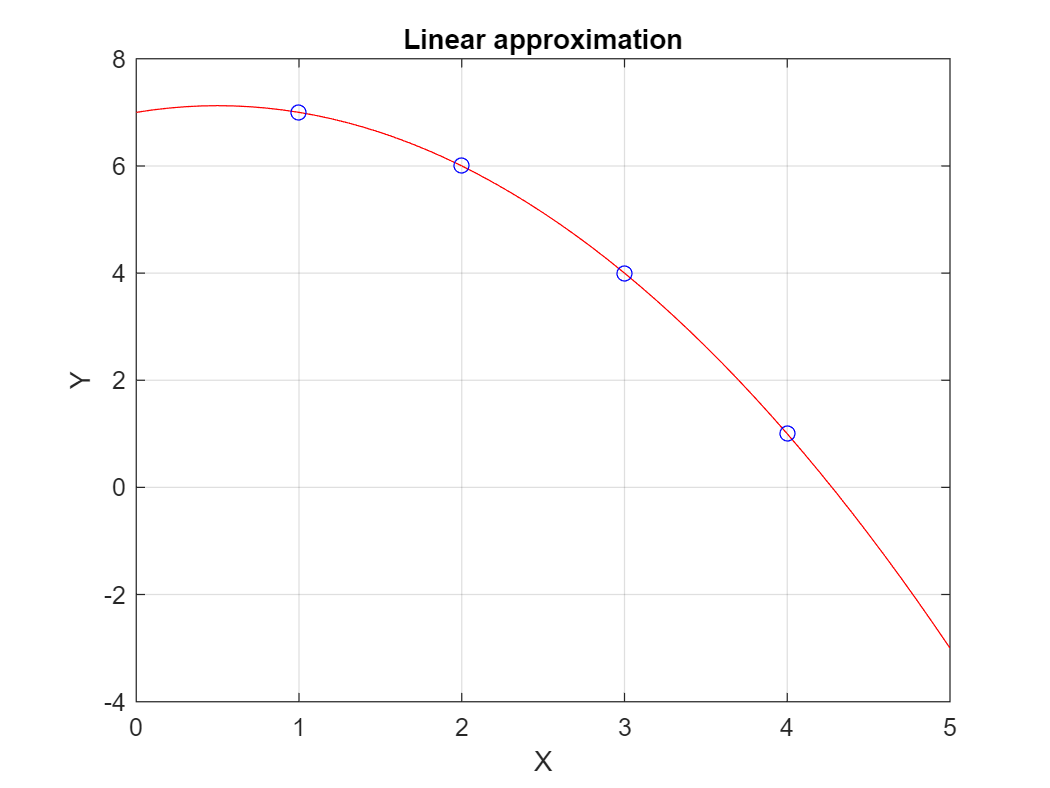


x1=0:0.1:5;
y1=a(1)*x1.^2+a(2)*x1+a(3);
figure(1)
plot(x1,y1,'r');
hold on;
plot(x,y,'bo');
hold off; grid on;
xlabel('X'), ylabel('Y'),
title('Linear approximation')


x1=1:4;
y1=sol.a*x1+sol.b;
e=(y1-y).^2;
stem(e)
title('error')

polyval(a,x)

ans =     7.0000    6.0000    4.0000    1.0000


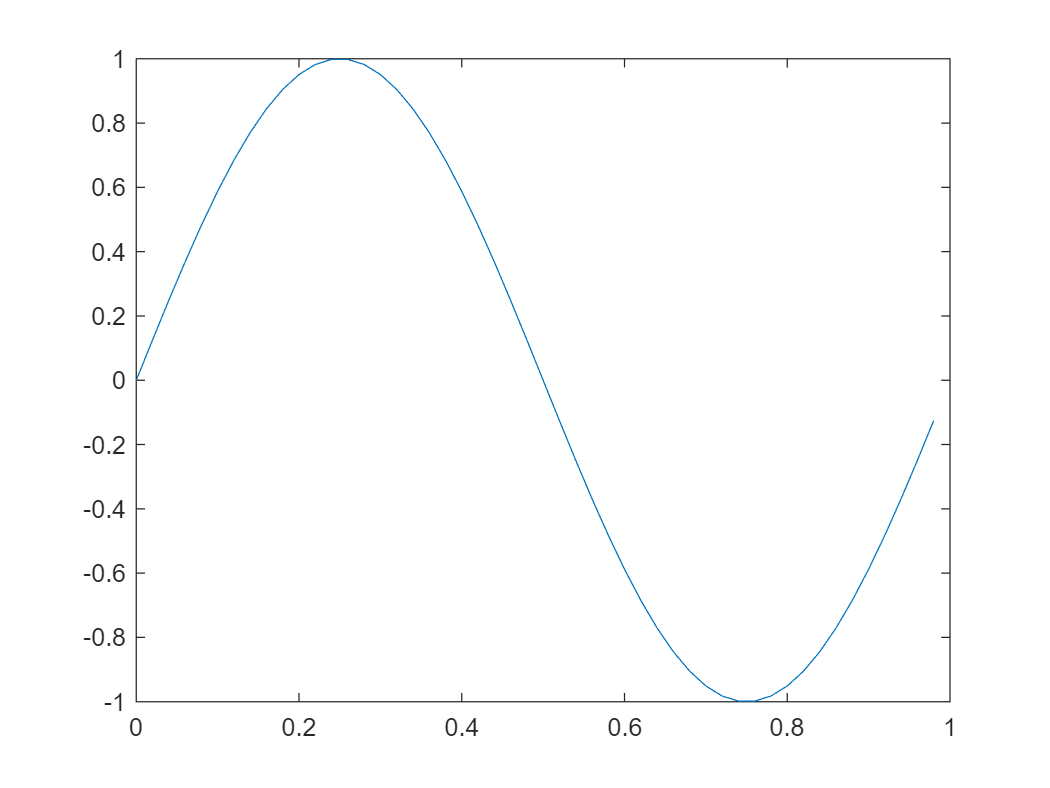

fs=50;
dt=1/fs;
t=0:dt:1-dt;
x=sin(2*pi*1*t);
plot(t,x);

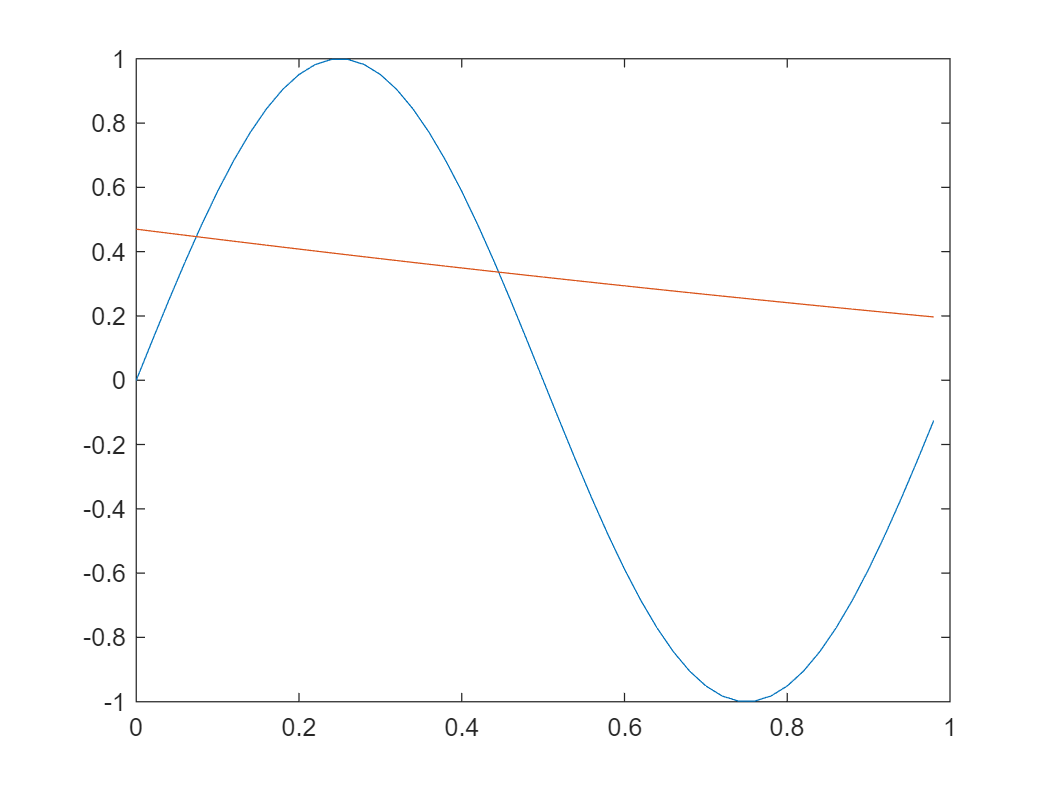


p1=polyfit(x,t,2);
x1=p1(1)*t.^2+p1(2)*t+p1(3);
plot(t,x);hold on
plot(t,x1);hold off

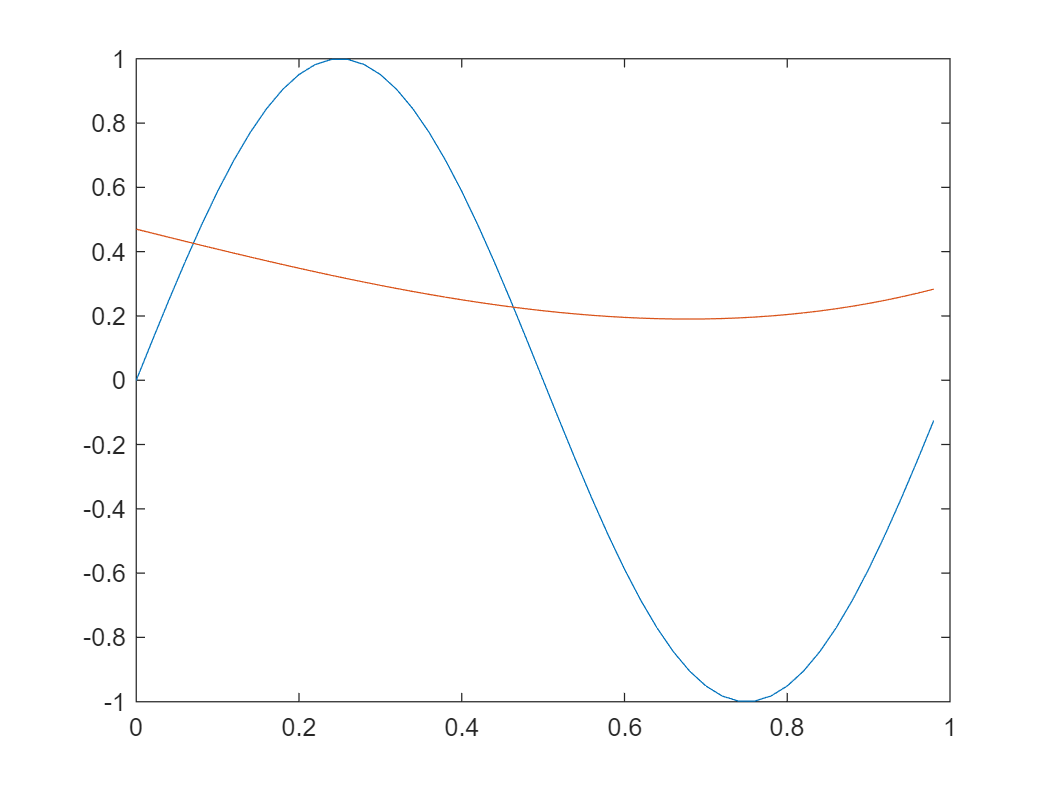


p2=polyfit(x,t,3);
x1=p2(1)*t.^3+p2(2)*t.^2+p2(3)*t+p2(4);
plot(t,x);hold on
plot(t,x1);hold off

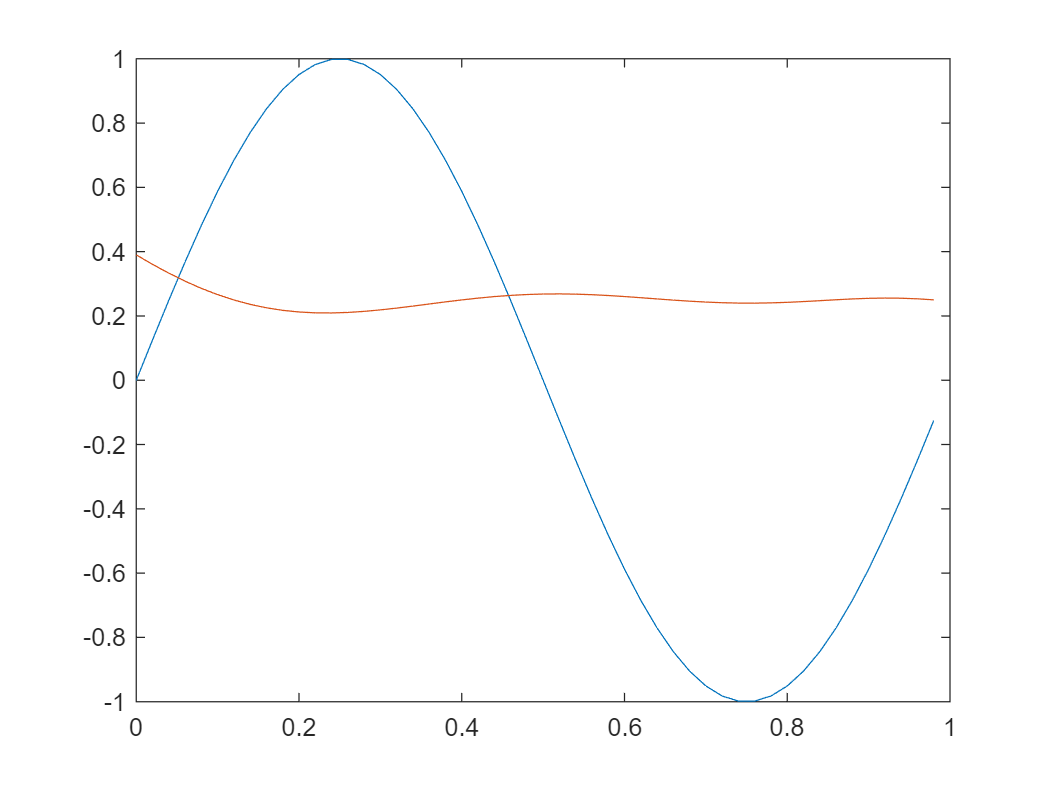


p1=polyfit(x,t,10);
x1=polyval(p1,t);
plot(t,x);hold on
plot(t,x1);hold off

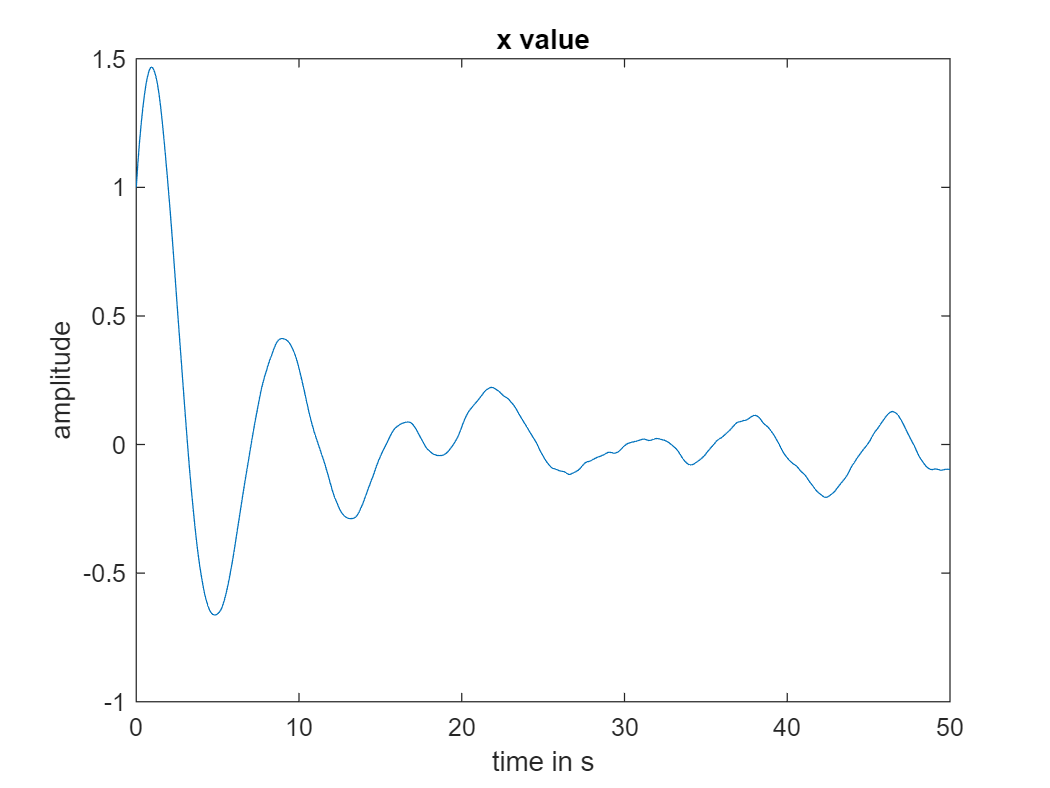

c1=1;
k1=2;
m1=3;
out=sim("untitle2d.slx");
plot(out.tout,out.x);
xlabel('time in s')
ylabel('amplitude')
title('x value')

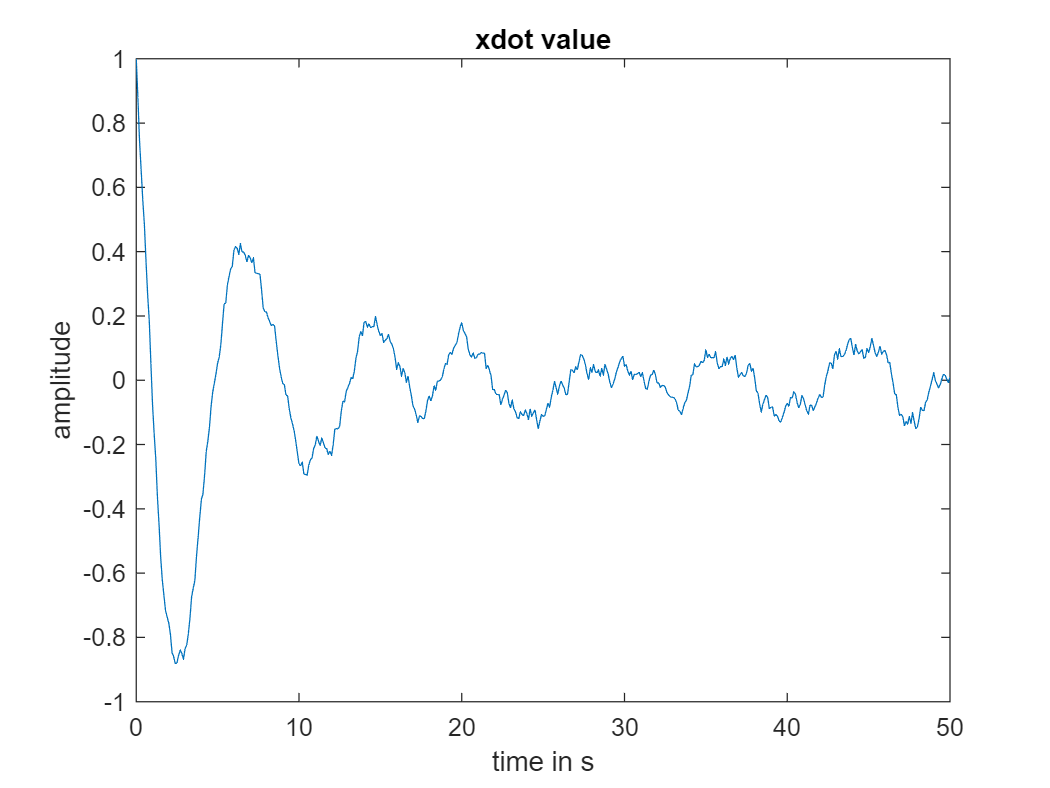

plot(out.tout,out.xdot);
xlabel('time in s')
ylabel('amplitude')
title('xdot value')

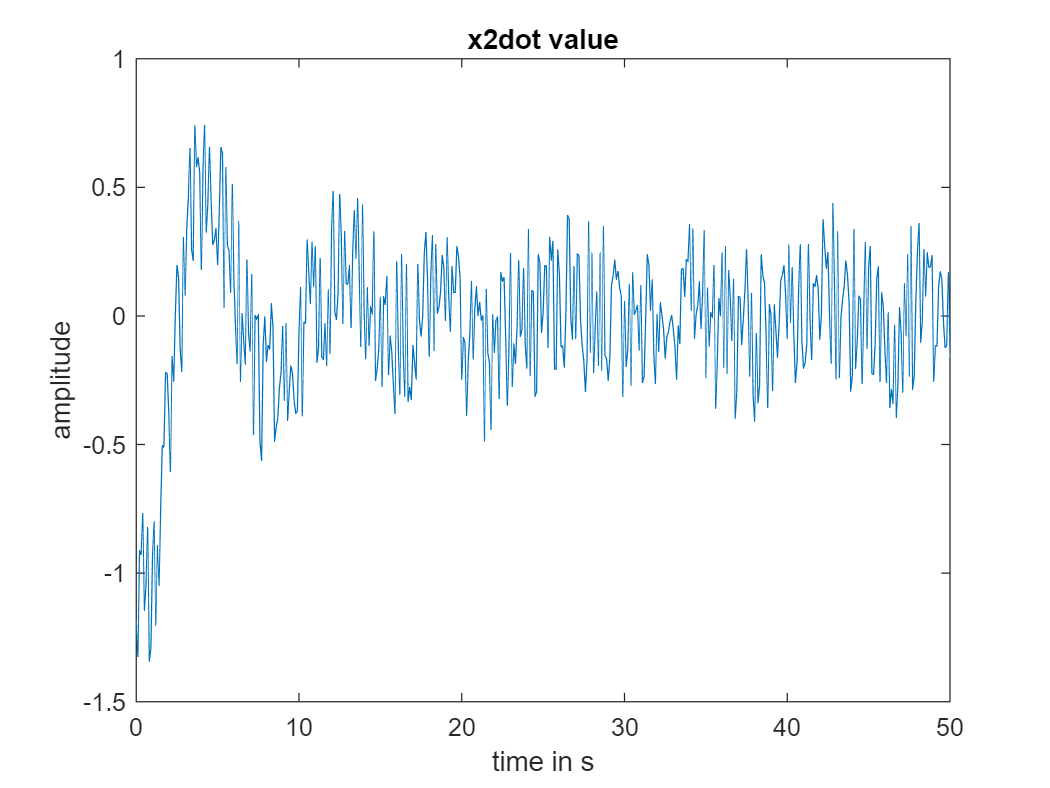

plot(out.tout,out.x2dot);
xlabel('time in s')
ylabel('amplitude')
title('x2dot value')

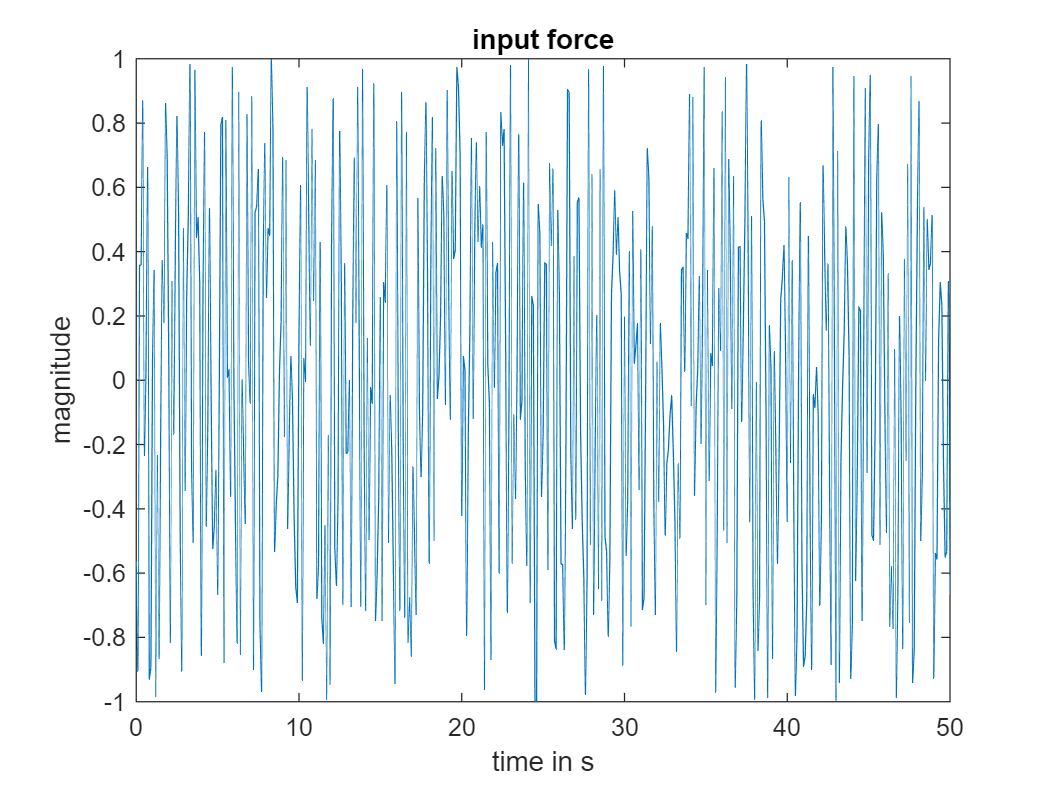

plot(out.tout,out.f);
xlabel('time in s')
ylabel('magnitude')
title('input force')


syms m c k

X=[(out.x2dot'*out.x2dot) (out.x2dot'*out.xdot) (out.x2dot'*out.x);...
    (out.x2dot'*out.xdot) (out.xdot'*out.xdot) (out.xdot'*out.x);...
    (out.x2dot'*out.x) (out.xdot'*out.x) (out.x'*out.x)]

X =    43.8754   -6.4100  -35.4597
   -6.4100   25.5402   -4.4535
  -35.4597   -4.4535   55.1749




X2=[sum(out.x2dot.*out.x2dot) sum(out.x2dot.*out.xdot) sum(out.x2dot.*out.x);...
    sum(out.x2dot.*out.xdot) sum(out.xdot.*out.xdot) sum(out.xdot.*out.x);...
    sum(out.x2dot.*out.x) sum(out.xdot.*out.x) sum(out.x.*out.x)]

X2 =    43.8754   -6.4100  -35.4597
   -6.4100   25.5402   -4.4535
  -35.4597   -4.4535   55.1749



a=[m;c;k]

$$a = \left(\begin{array}{c} m\\ c\\ k \end{array}\right)$$

F=[out.f'*out.x2dot;out.f'*out.xdot;out.f'*out.x]

F =    54.2966
   -2.5970
   -0.4829


sol=solve(X*a==F,a)

sol = struct with fields:
    m: 13140789615639936736482603362872838789094897873649/4380263205213313398587880761594579036397459396742
    c: 8760526410426626029461130869736387245240663040075/8760526410426626797175761523189158072794918793484
    k: 4380263205213311293147839014456435829586165818043/2190131602606656699293940380797289518198729698371


X\F

ans =     3.0000
    1.0000
    2.0000


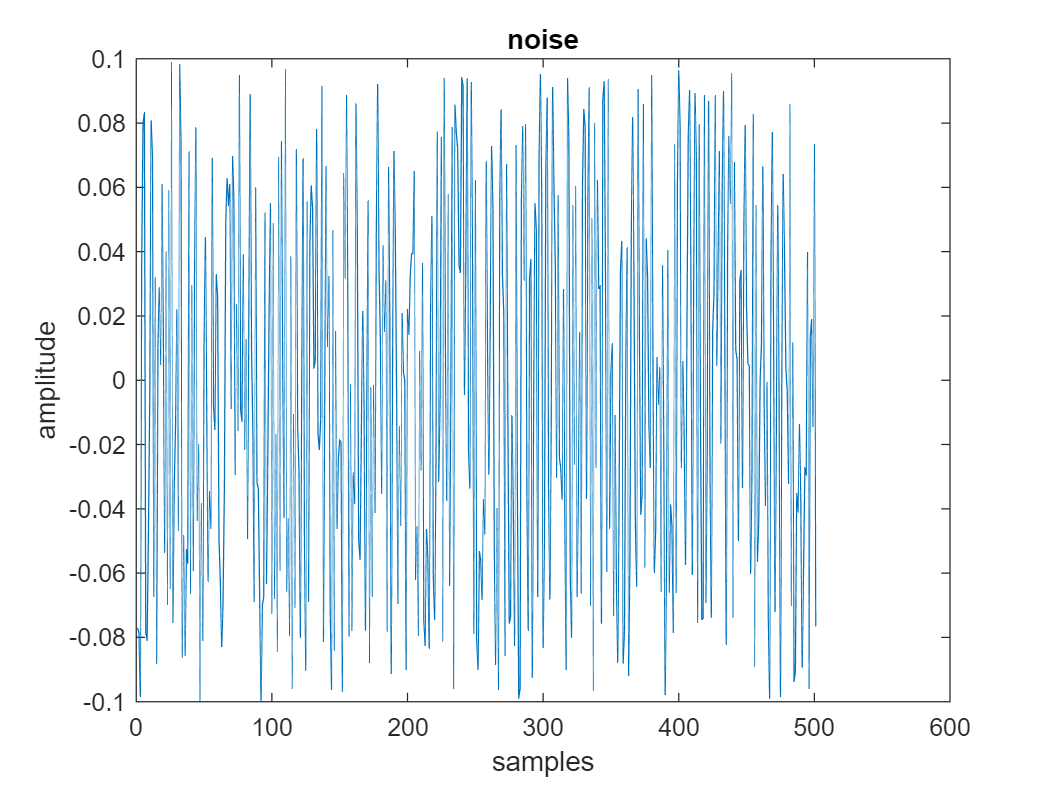


noise=(rand(1,length(out.x))'-0.5).*0.2;
plot(noise);
xlabel('samples')
ylabel('amplitude')
title('noise')

noise2=(rand(1,length(out.x))'-0.5).*0.2;
noise3=(rand(1,length(out.x))'-0.5).*0.2;
out.x=out.x+noise;
out.xdot=out.xdot+noise2;
out.x2dot=out.x2dot+noise3;
X2=[sum(out.x2dot.*out.x2dot) sum(out.x2dot.*out.xdot) sum(out.x2dot.*out.x);...
    sum(out.x2dot.*out.xdot) sum(out.xdot.*out.xdot) sum(out.xdot.*out.x);...
    sum(out.x2dot.*out.x) sum(out.xdot.*out.x) sum(out.x.*out.x)]

X2 =    46.9189   -6.7179  -35.8654
   -6.7179   26.7160   -4.3990
  -35.8654   -4.3990   56.5468



a=[m;c;k]

$$a = \left(\begin{array}{c} m\\ c\\ k \end{array}\right)$$

F=[out.f'*out.x2dot;out.f'*out.xdot;out.f'*out.x]

F =    54.9811
   -3.0729
   -0.0756


sol=solve(X2*a==F,a)

sol = struct with fields:
    m: 7160280796361442296306353460630213467316357441115/2759534238780642206198985878212232952507360888706
    c: 4518406109874668695547336847859061601785629049365/5519068477561284412397971756424465905014721777412
    k: 2356774410973322648990691729067917200477352968852/1379767119390321103099492939106116476253680444353


X2\F

ans =     2.5947
    0.8187
    1.7081


Adding noise decreaced the accuracy of our results